
clear;

csvFolderName = "StockVibro";
clockTimeLimit = 2.5; % 体験時間 (s)
stopTime = clockTimeLimit;
stopTable = table(stopTime);
writetable(stopTable, csvFolderName + '\' + "stop.csv");

Stock Left

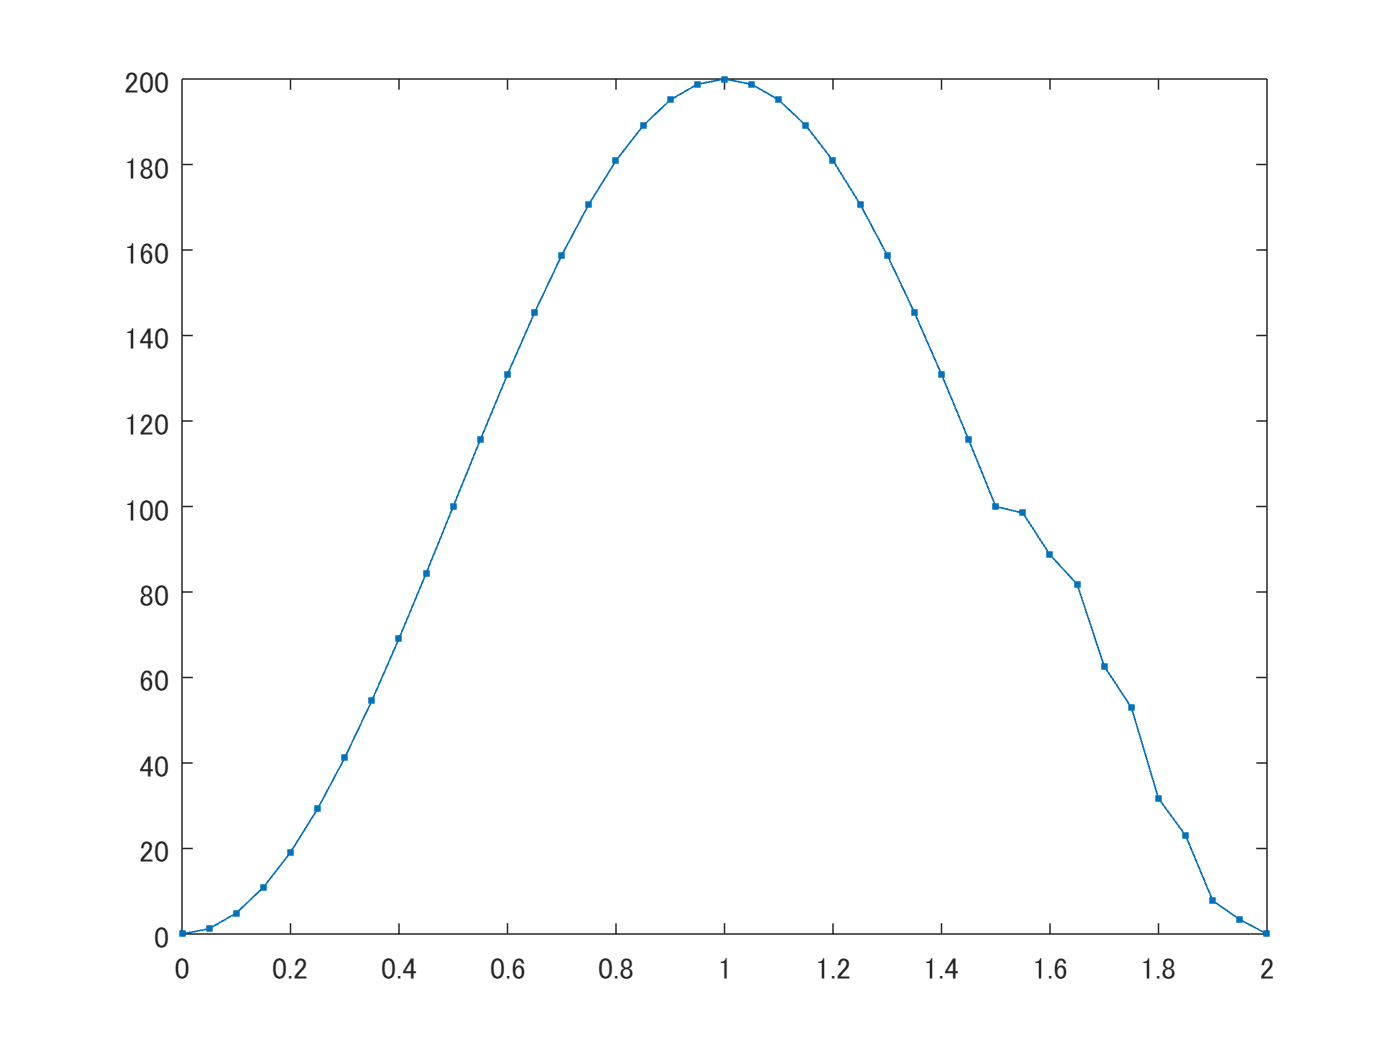

dt = 0.05;
T = 2;
xLimit = 200; % 単位 (mm)
clockTime = (0:dt:T)';

upDurationRatio = 2;
downDurationRatio = 1;
dragDurationRatio = 1;

upDurationRate = upDurationRatio/(upDurationRatio + downDurationRatio + dragDurationRatio);
downDurationRate = downDurationRatio/(upDurationRatio + downDurationRatio + dragDurationRatio);
dragDurationRate = dragDurationRatio/(upDurationRatio + downDurationRatio + dragDurationRatio);

F = 9; % 振動周波数 Hz
Amp = 3; % 振動振幅 mm
% Amp*rand(size((0:dt:3*T/4)'));

x = [
    xLimit * (cos(pi*(0:dt:T*upDurationRate-dt)'/(T*upDurationRate) + pi) + 1)*0.5;
    xLimit * (cos((pi/2)*(0:dt:T*downDurationRate-dt)'/(T*downDurationRate)) + 1)*0.5;
    xLimit/2 * (cos(pi*(0:dt:T*dragDurationRate)'/(T*dragDurationRate)) + 1)*0.5 + Amp*sin(2*pi*F*(0:dt:T*dragDurationRate)');
    ];
figure;
plot(clockTime, x, '.-');

% StockVibroCSV = table(clockTime, x)
% writetable(StockVibroCSV, csvFolderName + '\' + "StockVibro.csv");

clockTime = [0, T*upDurationRate, (0:dt:T*dragDurationRate) + T*upDurationRate + T*downDurationRate]'

clockTime =          0
    1.0000
    1.5000
    1.5500
    1.6000
    1.6500
    1.7000
    1.7500
    1.8000
    1.8500


deltaTime = [T*upDurationRate, T*downDurationRate, dt*ones(size(0:dt:T*dragDurationRate))]'

deltaTime =     1.0000
    0.5000
    0.0500
    0.0500
    0.0500
    0.0500
    0.0500
    0.0500
    0.0500
    0.0500


useLinearMotion = [0; 0; ones(size((0:dt:T*dragDurationRate)'))]

useLinearMotion =      0
     0
     1
     1
     1
     1
     1
     1
     1
     1


position = [xLimit; xLimit/2; xLimit/2 * (cos(pi*(0:dt:T*dragDurationRate)'/(T*dragDurationRate)) + 1)*0.5 + Amp*sin(2*pi*F*(0:dt:T*dragDurationRate)');]

position =   200.0000
  100.0000
  100.0000
   98.4799
   88.6875
   81.8163
   62.5977
   53.0000
   31.6960
   23.0378



StockVibroCSV = table(clockTime, deltaTime, position, useLinearMotion)

StockVibroCSV = 13×4 table
    clockTime    deltaTime     position     useLinearMotion
    _________    _________    __________    _______________

         0            1              200           0       
         1          0.5              100           0       
       1.5         0.05              100           1       
      1.55         0.05            98.48           1       
       1.6         0.05           88.687           1       
      1.65         0.05           81.816           1       
       1.7         0.05           62.598           1       
      1.75         0.05               53           1       
       1.8         0.05           31.696           1       
      1.85         0.05           23.038           1       
       1.9         0.05           7.7858           1       
      1.95         0.05           3.3742           1       
         2         0.05       3.3065e-15           1       


writetable(StockVibroCSV, csvFolderName + '\' + "StockVibro.csv");


function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end